clear; close all; clc;

path1 = 'E:\桌面\1124\R';
file1 = dir(fullfile(path1, '*.tif'));

path2 = 'E:\桌面\1124\R1';
[status, msg] = mkdir(path2);

for i = 1 : size(file1, 1)
    
    filepathname1 = fullfile(path1, file1(i).name);
    data1 = imread(filepathname1);
    
    if numel(size(data1)) == 3
        data2 = im2double(rgb2gray(data1));
    elseif max(data1, [], 'all') > 1
        data2 = im2double(data1);
    else
        data2 = im2double(data1);
    end
    
    datamin = min(data2, [], "all");
    datamax = max(data2, [], "all");
    
    data2 = (data2 - datamin) / (datamax - datamin);
    data2 = im2uint16(data2);
    imshow(data2)
    file1(i).name(end-3:end) = '.png';
    imwrite(data2, fullfile(path2, file1(i).name));
    
end

close all; clear; clc;

path1 = 'E:\桌面\1124\C1';
file1 = dir(fullfile(path1, '*.png'));
path2 = 'E:\桌面\1124\M1';
file2 = dir(fullfile(path2, '*.png'));

save_path = 'E:\桌面\1124\R';
[status, msg] = mkdir(save_path);

max_a = 2^8-1;
max_b = 2^1-1;
min_c = 0;
mode = 1;

for i = 1 : 1
    
    data_1 = imread(fullfile(path1, file1(i).name));
    data_2 = imread(fullfile(path2, file2(2).name));
    [a, b] = size(data_2);
    
    if numel(size(data_1)) == 3
        data = rgb2gray(data_1);
    else
        data = data_1;
    end
    
    if mode == 1
        data = imresize(data, [a, b]);
        imwrite(data, fullfile(path1, file1(i).name))
        
        se = strel('disk',3);
        mask1 = imclose(imbinarize(data), se);
        figure;imshow(mask1);
        mask2 = imclose(edge(data), se);
        figure;imshow(mask2);
        mask3 = imclose(mask1+mask2, se); 
        figure;imshow(mask3);
        mask4 = bwareaopen(mask3, 32, 8);        
        figure;imshow(mask4);
        
    elseif mode == 2
        data = imresize(data, [a, b]);
        imwrite(data, fullfile(path1, file1(i).name))
        
        [~,threshold] = edge(data, 'sobel');
        fudgeFactor = 0.5;
        mask1 = edge(data, 'sobel', threshold * fudgeFactor);
        figure;imshow(mask1)
        se90 = strel('line', 3, 90);
        se0 = strel('line', 3, 0);
        figure;mask2 = imdilate(mask1, [se90 se0]);
        imshow(mask2)
        mask3 = imfill(mask2, 'holes');
        figure;imshow(mask3)
        mask4 = imclearborder(mask3, 8);
        figure;imshow(mask4)
        seD = strel('diamond',1);
        mask5 = imerode(imerode(mask4, seD), seD);
        figure;imshow(mask5)
    end
    
    figure;imshow(data_2);
    for r = 1 : size(mask3, 1)
        for c = 1 : size(mask3, 2)
            if mask3(r, c) == 0
                data_2(r, c) = min_c;
            elseif mask3(r, c) == 1
                
            end
        end
    end    
    figure;imshow(data_2);
    
    data_2 = im2uint16(data_2);
    imwrite(data_2, fullfile(save_path, file2(2).name))
    
end

clear; close all; clc;

path1 = 'E:\桌面\1124\C1';
file1 = dir(fullfile(path1, '*.png'));

path2 = 'E:\桌面\1124\R1';
file2 = dir(fullfile(path2, '*.png'));

path3 = 'E:\桌面\1124\Image1';
[status, msg] = mkdir(path3);

path4 = 'E:\桌面\1124\Label1';
[status, msg] = mkdir(path4);

x = 200;
y = 200;
step = 50;

j = 1;
for i = 1 : size(file1, 1)
    
    filepathname1 = fullfile(path1, file1(i).name);
    data1 = imread(filepathname1);
    
    filepathname2 = fullfile(path2, file2(i).name);
    data2 = imread(filepathname2);
    
    [a, b] = size(data1);
    step = 50;
    n = floor((a-x) / step);
    m = floor((b-y) / step);
    
    k = 1;
    for k1 = 1 : n
        for k2 = 1 : m
            dataxy1 = data1(1+(k1-1)*step:x+(k1-1)*step, 1+(k2-1)*step:y+(k2-1)*step);
            dataxy2 = data2(1+(k1-1)*step:x+(k1-1)*step, 1+(k2-1)*step:y+(k2-1)*step);
            blacknum(j) = x*y - length(find(dataxy2 == 0));
            if blacknum(j) >= 1960
                name1 = strcat(file1(i).name(1:end-4), '_', num2str(k), file1(i).name(end-3:end));
                filepathname3 = fullfile(path3, name1);
                imwrite(dataxy1, filepathname3);
                
                name2 = strcat(file2(i).name(1:end-4), '_', num2str(k), file2(i).name(end-3:end));
                filepathname4 = fullfile(path4, name2);
                imwrite(dataxy2, filepathname4);
            end
            k = k + 1;
            j = j + 1;
        end
    end
end
histogram(blacknum, 20);

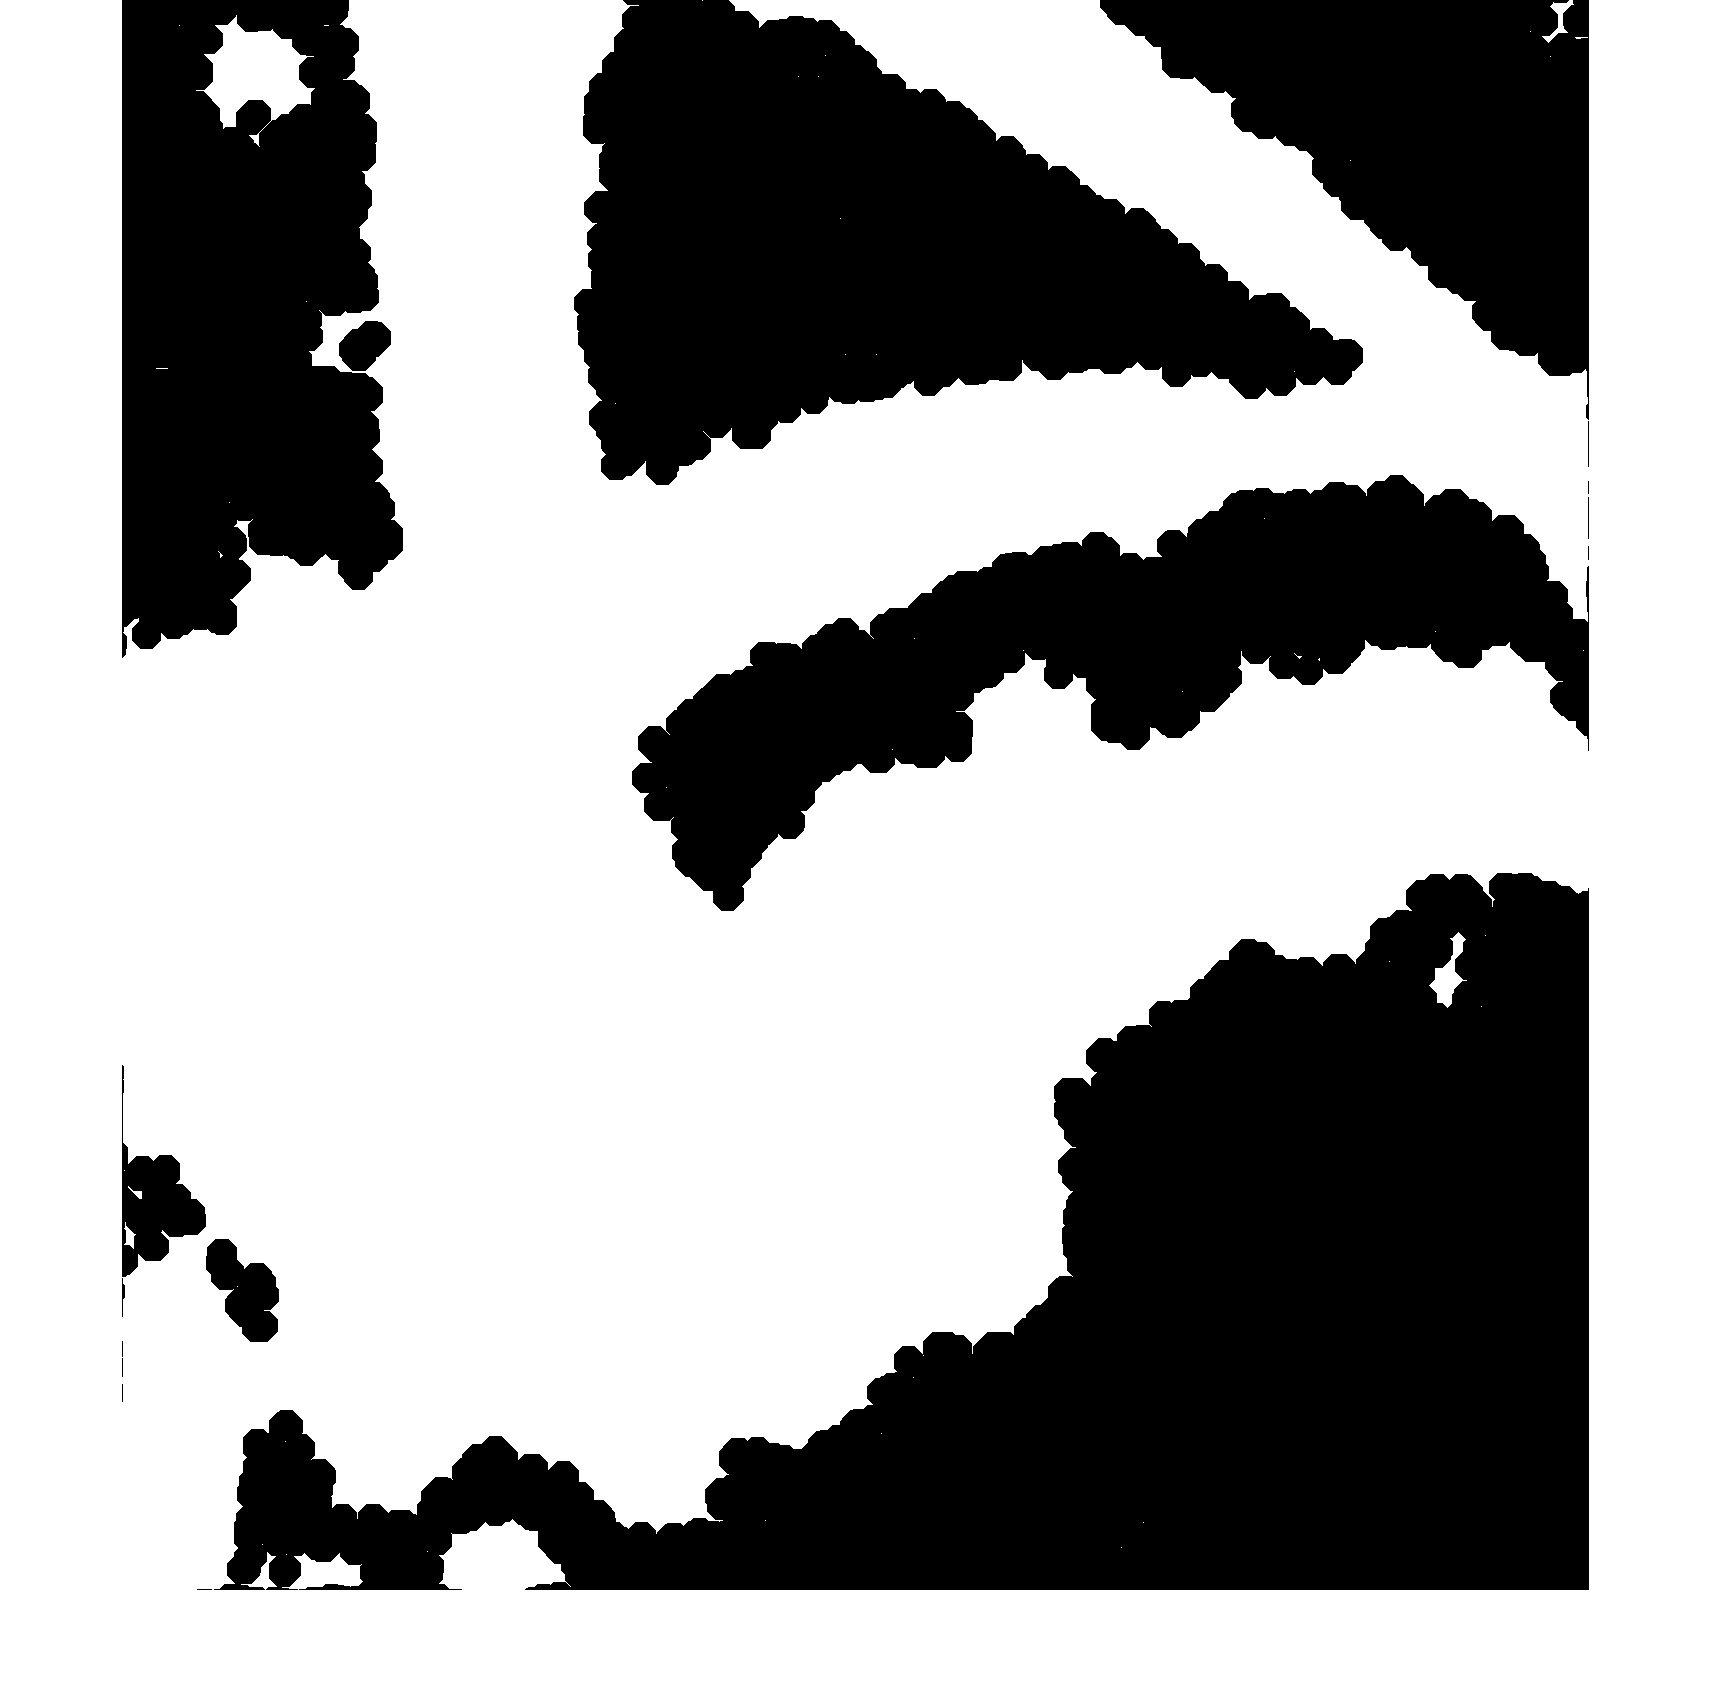

clear; close all; clc;

path1 = 'E:\桌面\1112tublin\Image1';
file1 = dir(fullfile(path1, '*.png'));

path2 = 'E:\桌面\1112tublin\Label1';
file2 = dir(fullfile(path2, '*.png'));

path3 = 'E:\桌面\1112tublin\Image2';
[status, msg] = mkdir(path3);

path4 = 'E:\桌面\1112tublin\Label2';
[status, msg] = mkdir(path4);

for i = 1 : size(file1, 1)
    
    filepathname1 = fullfile(path1, file1(i).name);
    data1 = imread(filepathname1);
    data11 = fliplr(data1);
    
    filepathname2 = fullfile(path2, file2(i).name);
    data2 = imread(filepathname2);
    data22 = fliplr(data2);
    
    k = 1;
    for j = 1 : 4
        dataxy1 = rot90(data1, j);
        dataxy2 = rot90(data2, j);
        
        name1 = strcat(file1(i).name(1:end-4), '_', num2str(k), file1(i).name(end-3:end));
        filepathname3 = fullfile(path3, name1);
        imwrite(dataxy1, filepathname3);
        
        name2 = strcat(file2(i).name(1:end-4), '_', num2str(k), file2(i).name(end-3:end));
        filepathname4 = fullfile(path4, name2);
        imwrite(dataxy2, filepathname4);
        k = k + 1;
    end
    
    for j = 1 : 4
        dataxy1 = rot90(data11, j);
        dataxy2 = rot90(data22, j);
        
        name1 = strcat(file1(i).name(1:end-4), '_', num2str(k), file1(i).name(end-3:end));
        filepathname3 = fullfile(path3, name1);
        imwrite(dataxy1, filepathname3);
        
        name2 = strcat(file2(i).name(1:end-4), '_', num2str(k), file2(i).name(end-3:end));
        filepathname4 = fullfile(path4, name2);
        imwrite(dataxy2, filepathname4);
        k = k + 1;
    end
    
end